# **Introductory script illustrating how to run an SVM classifier to measure discrimination performance between 2 stimuli.**

*This tutorial generates ISETBio scenes representing a test Gabor stimulus and a null (zero contrast) stimulus. Stimuli are passed through human wavefront-based optics, and cone mosaic excitation responses are computed. The dimensionality of the computed responses  is reduced by projecting the responses into the space defined by their first 2 principal components. The reduced dimensionality responses are used to train a binary SVM classifier and the performance of the classifier at identifying the test from the null stimulus is assessed ivia a 10-fold crossvalidation. Along the way, various steps of the pipeline are visualzed.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2019*

# **Step 1.** Create a presentation display

We employ an existing display specification, here an Apple LCD display.

% Create presentation display and place it 57 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

# **Step 2.** Create the test stimulus - a 60% contrast, 16 c/deg Gabor

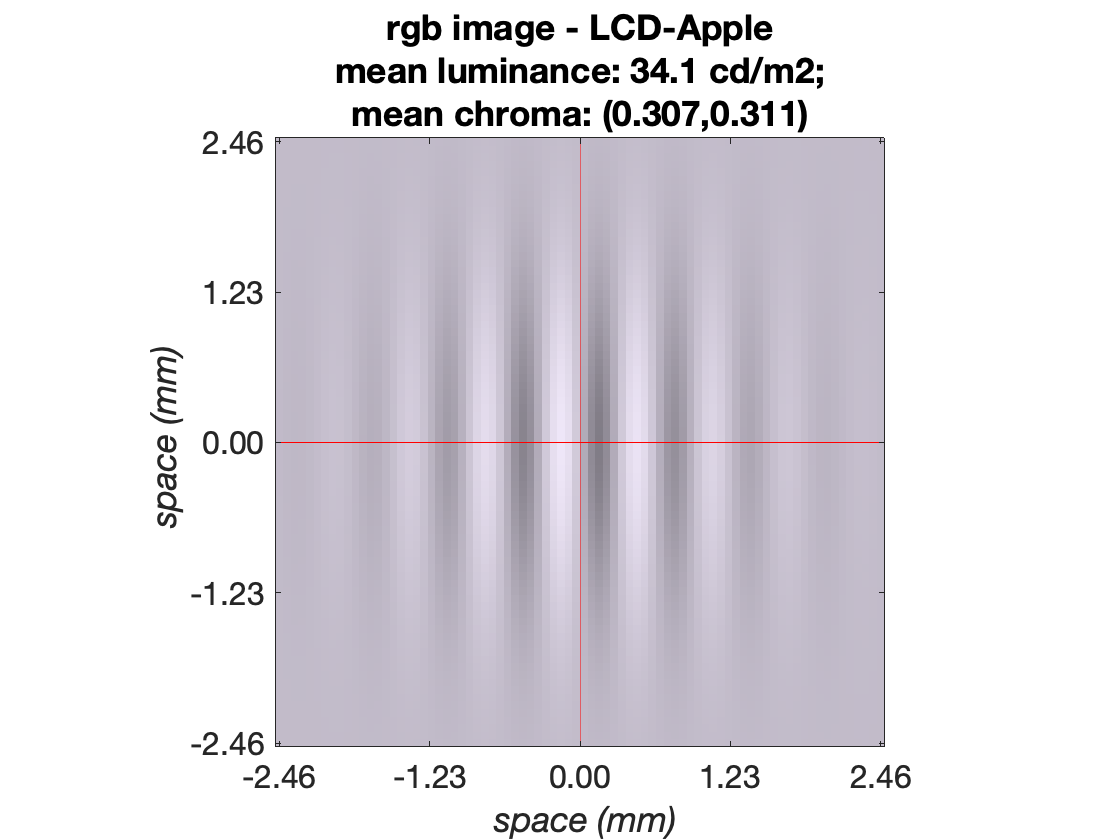

% Parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 16, ... % 16 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase in degrees
    'sizeDegs', 0.5, ...                    % 0.5 x 0.5 degrees
    'sigmaDegs', 0.3/3, ...                 % sigma of Gaussian envelope, in degrees
    'contrast', 60/100,...                  % 60% Michelson contrast
    'meanLuminanceCdPerM2', 34, ...         % 34 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the 10% Gabor stimulus as realized on the presentationDisplay
testScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 5);

% Visualize the generated scene
visualizeScene(testScene, ...
    'displayRadianceMaps', false);

# **Step 3.** Create the null stimulus - a 0% contrast Gabor

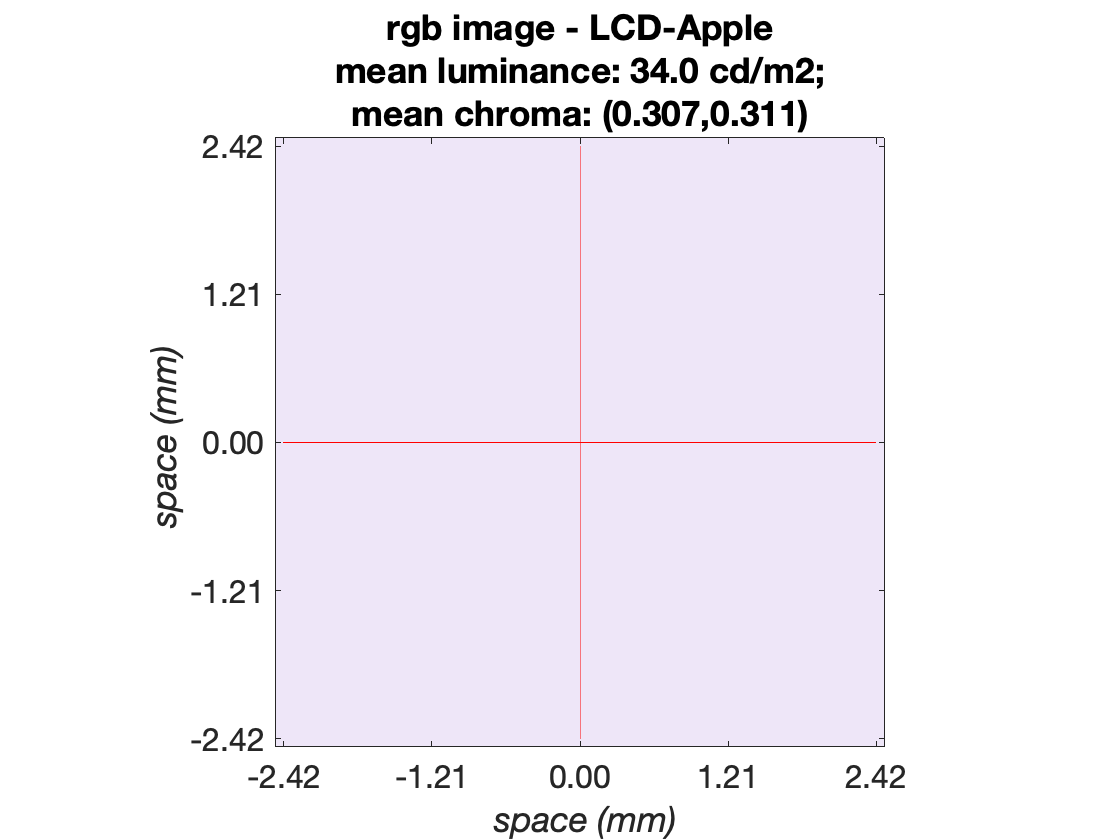

% Zero contrast for the null stimulus 
stimParams.contrast = 0.0;

% Generate a scene representing the 10% Gabor stimulus as realized on the presentationDisplay
nullScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize the generated scene
visualizeScene(nullScene, ...
    'displayRadianceMaps', false);

# **Step 4.** Compute the optical images of the 2 scenes

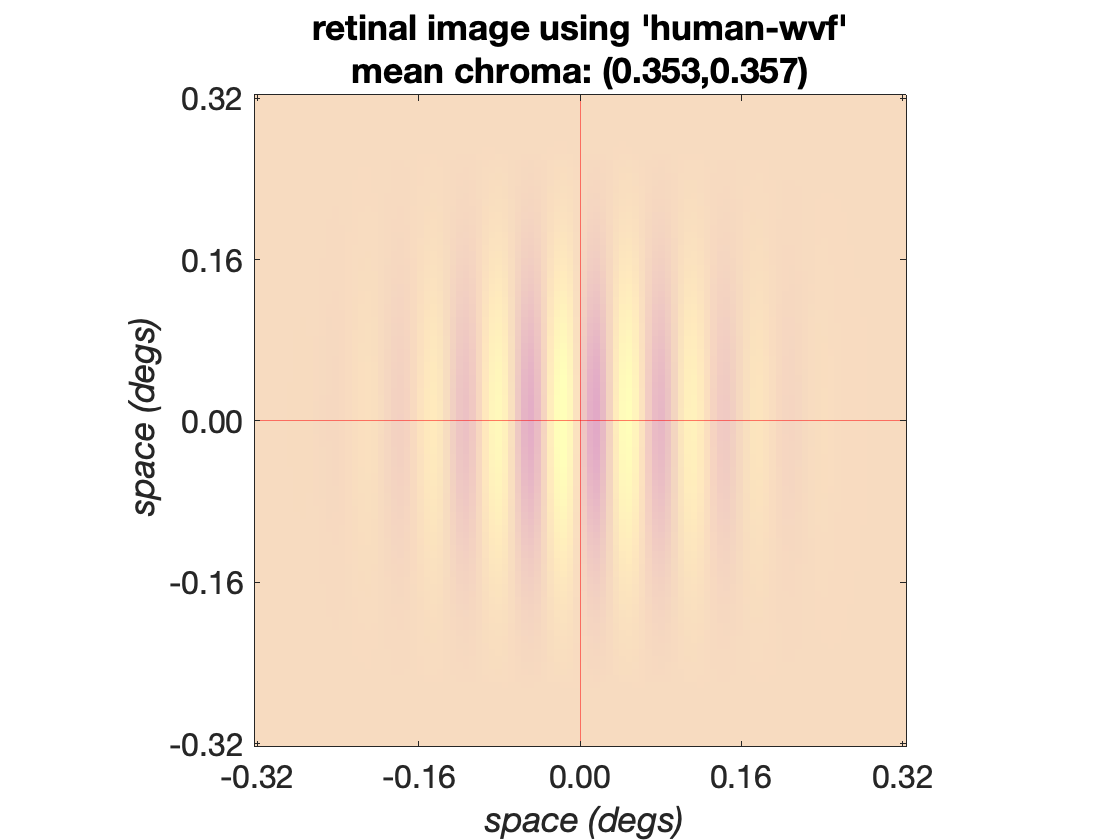

% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

% Compute the retinal image of the test stimulus
theTestOI = oiCompute(theOI, testScene);

% Compute the retinal image of the null stimulus
theNullOI = oiCompute(theOI, nullScene);

% Visualize the optical image of the test
visualizeOpticalImage(theTestOI, ...
    'displayRadianceMaps', false);

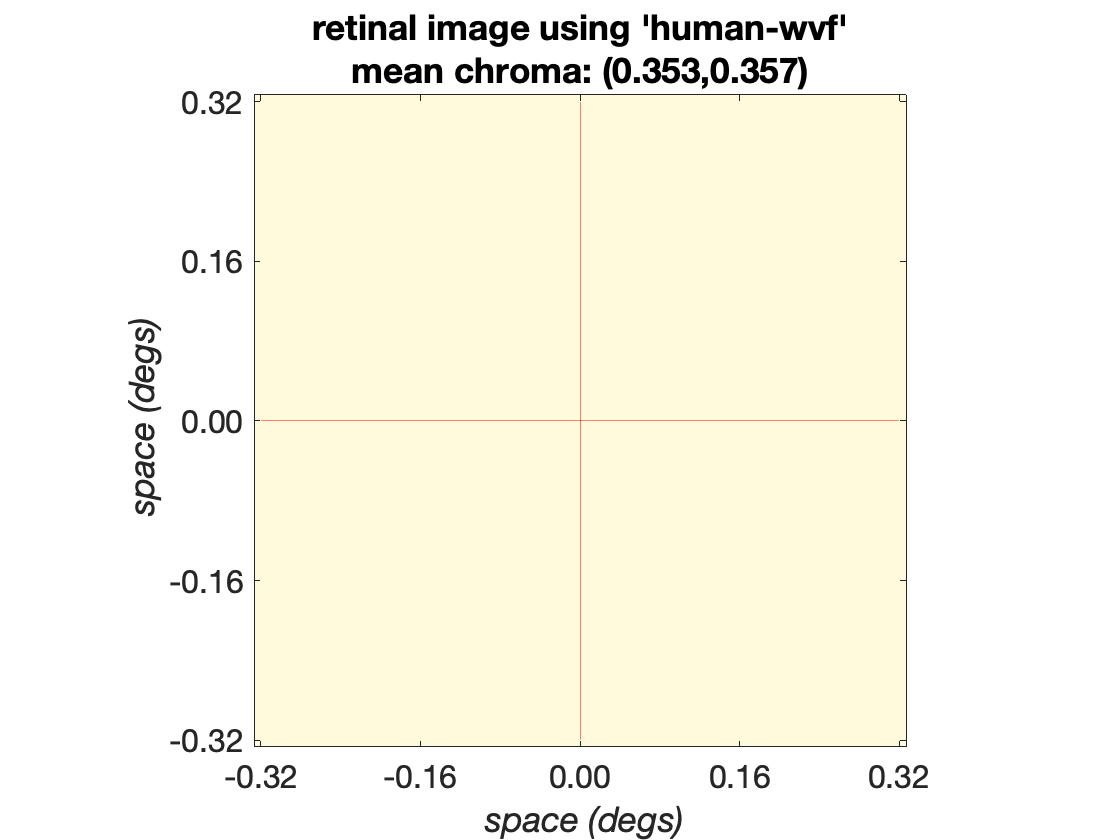


% Visualize the optical image of the test
visualizeOpticalImage(theNullOI, ...
    'displayRadianceMaps', false);

# **Step 5.** Create a cone mosaic object with a 10 msec integration window

% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...              % hex lattice sampling factor
   'fovDegs', stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 10/1000, ...            % 10 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations

Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 105.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.674698, Tolerange: 0.001000
Number of Delayun triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 105.00 113.77 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex 

# **Step 6a.** Compute a number of mosaic response instances to both the test and the null stimuli

Here we compute a number of response instances, each corresponding to a 10 msec stimulus exposure

% Generate 50 instances of zero movement eye movement paths. This step will
% take a few minutes to complete.
nTrialsNum = 50;
emPathLength = 1;
emPath = zeros(nTrialsNum, emPathLength, 2);

% Compute mosaic excitation responses to the test stimulus
coneExcitationsTest = theMosaic.compute(theTestOI, 'emPath', emPath);

% Compute mosaic excitation responses to the null stimulus
coneExcitationsNull = theMosaic.compute(theNullOI, 'emPath', emPath);

# **Step 6b.** Visualize the test and null stimulus responses

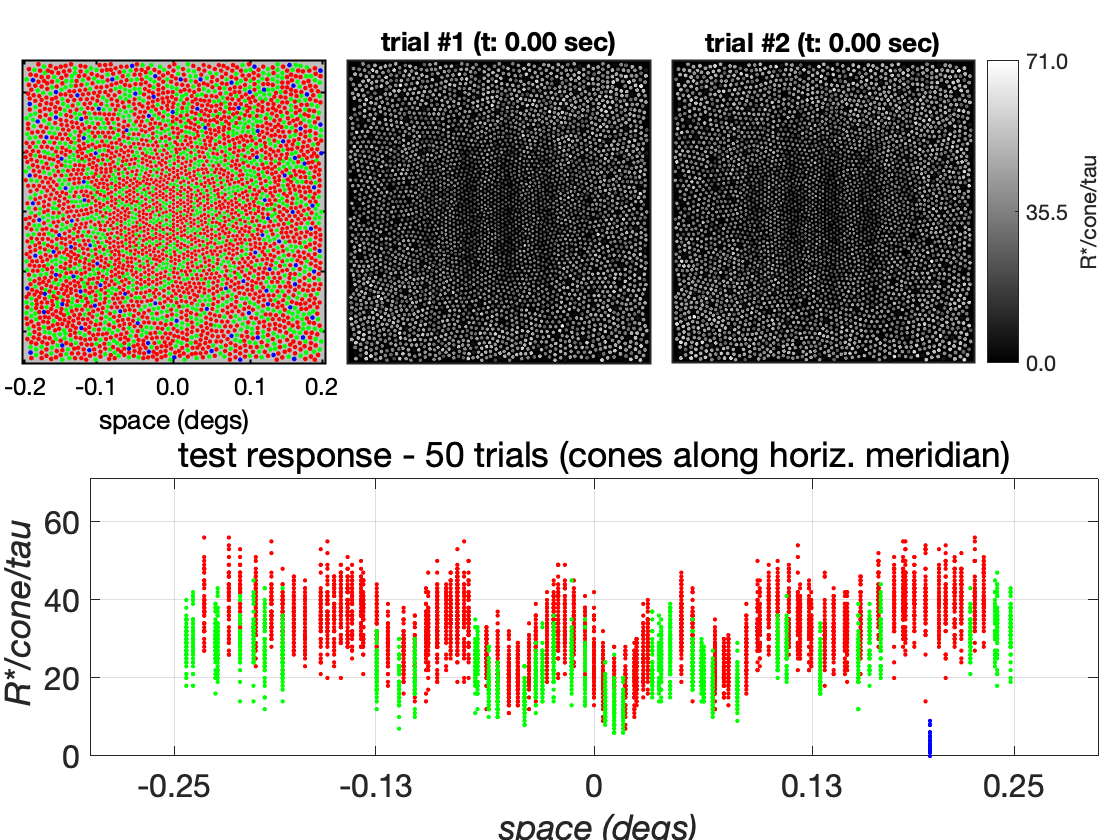

% Visualize cone mosaic and its cone excitation responses to the test stimulus
visualizeConeMosaicResponses(theMosaic, coneExcitationsTest, ...
    'R*/cone/tau', ...
    'customTitle', 'test response');

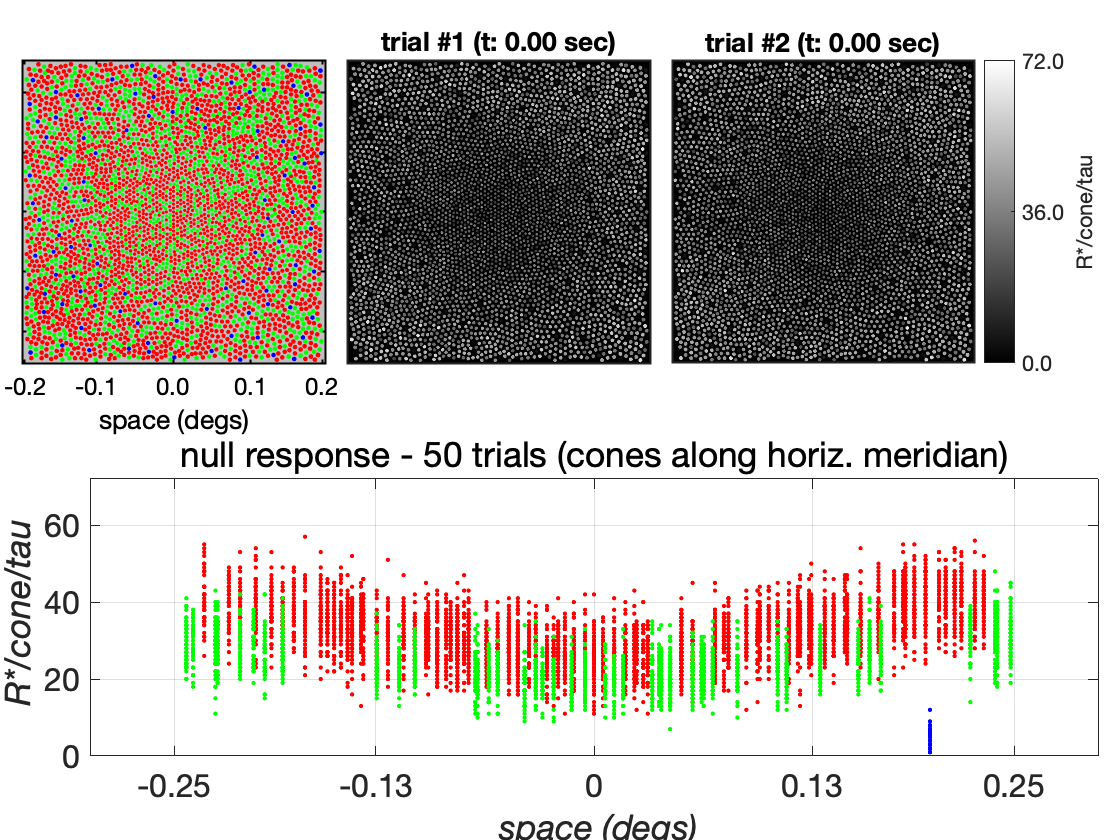


% Visualize cone mosaic and its cone excitation responses to the null stimulus
visualizeConeMosaicResponses(theMosaic, coneExcitationsNull, ...
    'R*/cone/tau', ...
    'customTitle', 'null response');

# **Step 7.** Arrange response vectors for binary classification

Assemble the response vectors into a classification matrix that simulates either a one interval task or a two-interval task.

% Simulate a 2AFC task 
taskIntervals = 2;
[classificationMatrix, classLabels] = generateSetUpForClassifier(theMosaic, ...
    coneExcitationsTest, coneExcitationsNull, taskIntervals);

# **Step 8.** Apply a data-reduction technique to reduce the dimensionality of the classification matrix.

Here we reduce the data dimensionality by projecting the response vectors into the space formed by their first N-principal components. The original classification matrix [nTrials x several thousands of cones] is reduced to [nTrials x PC components number]. Here we only use the first 2 PCs.

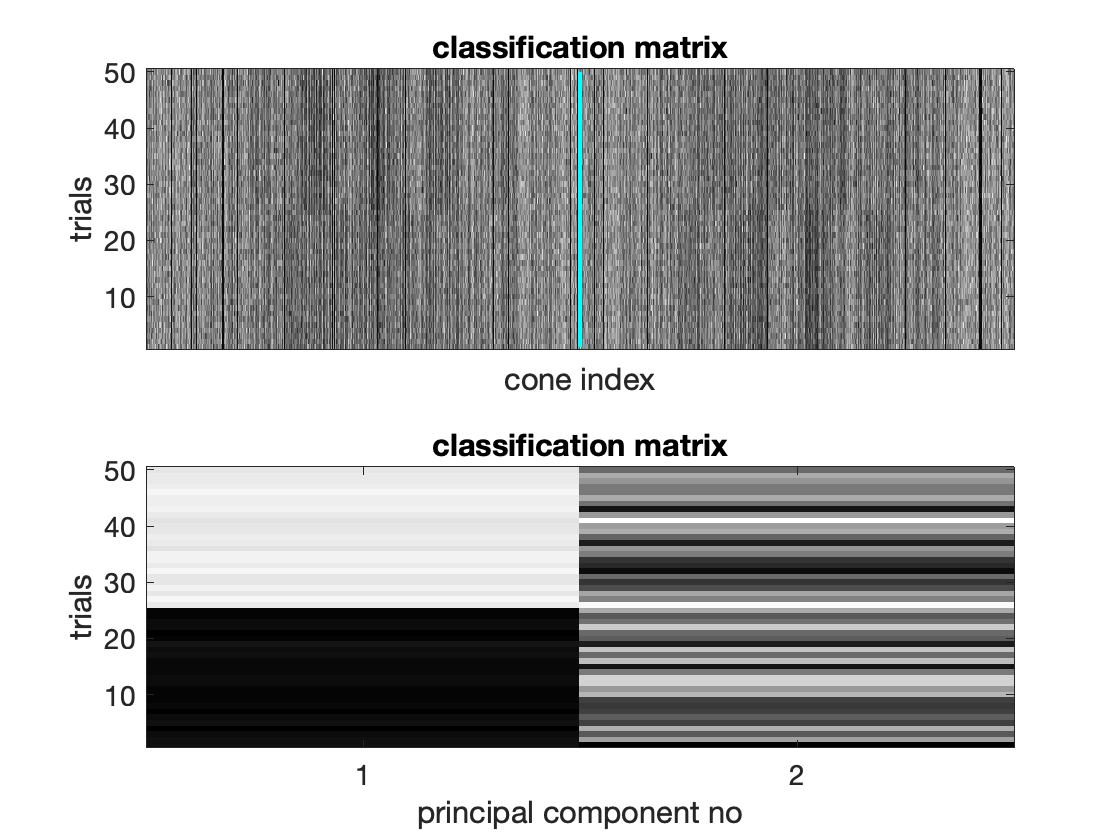

% Find principal components of the responses
[pcVectors, ~, ~, ~,varianceExplained] = pca(classificationMatrix);

% Project the responses onto the space formed by the first 4 PC vectors
pcComponentsNumForClassification = 2;
classificationMatrixProjection = classificationMatrix * pcVectors(:,1:pcComponentsNumForClassification);

% Visualize the classification matrix and its projection to the PC space
visualizeClassificationMatrices(classificationMatrix, classificationMatrixProjection, taskIntervals)

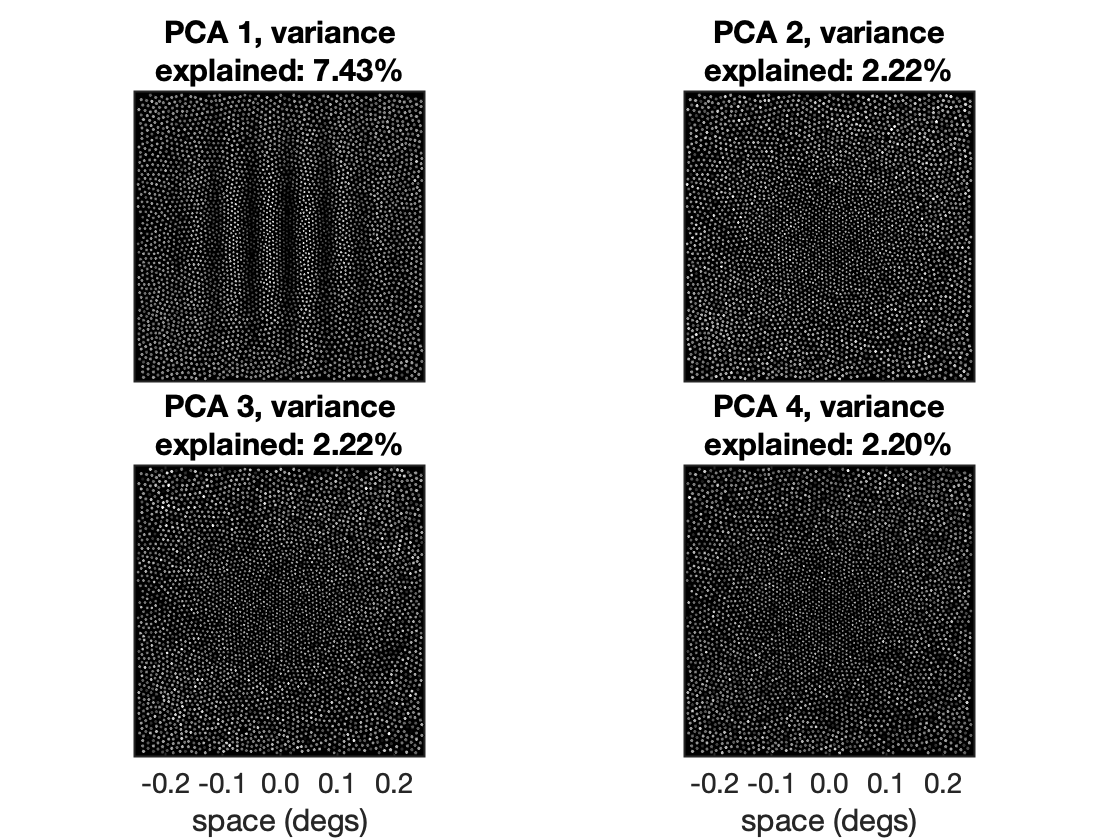


% Visualize the first 4 principal components. Note that only the first
% component contains some structure, which resembles the stimulus to be detected.
visualizePrincipalComponents(pcVectors, varianceExplained, theMosaic);

# **Step 9a.** Train a binary SVM classifier

Here we train a binary SVM classifier on the PC-projected response vectors, and visualize the classificied responses in 2 dimensional PC-based space as well as the separating hyperplane.

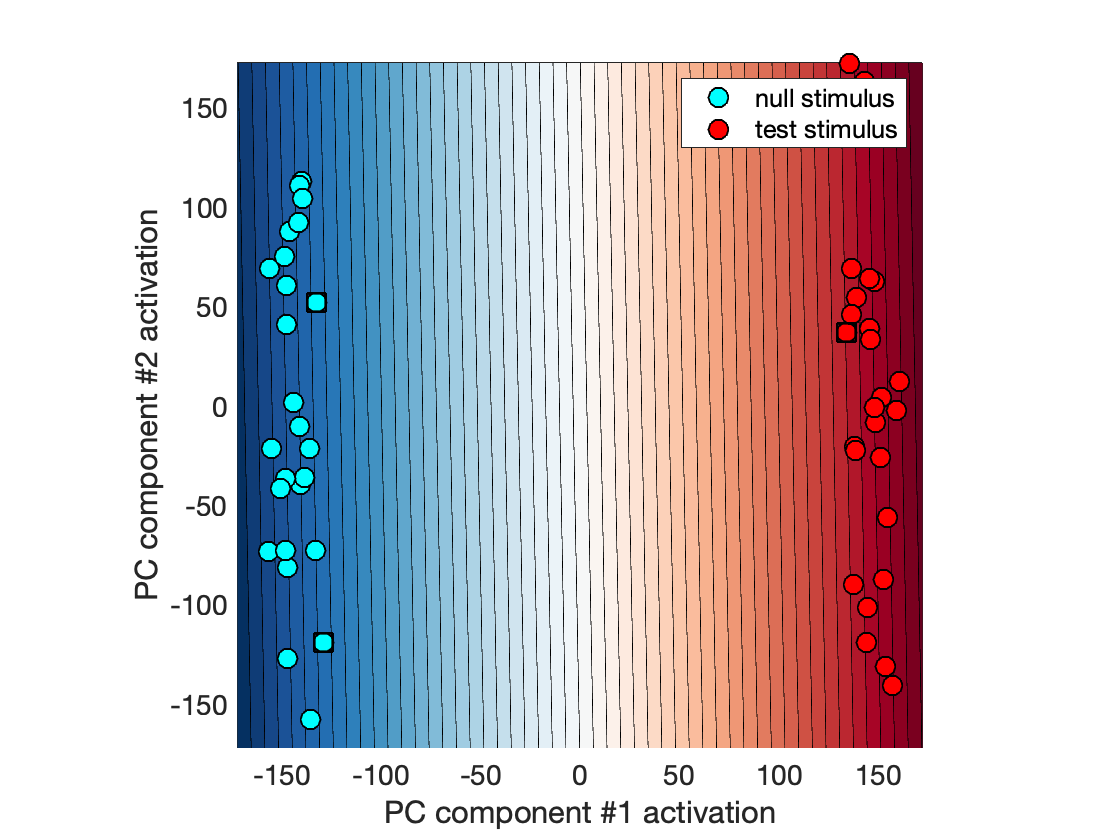

% Train a binary SVM classifier and visualize the support vectors in 2
% dimensions
svm = fitcsvm(classificationMatrixProjection,classLabels);

% Visualize the data along with the hyperplane computed by the SVM 
visualizeSVMmodel(svm, classificationMatrixProjection, classLabels);

# **Step 9b.** Measure performance of the SVM classifier using a 10-fold crossvalidation approach

Measure the performance of the SVM classifier using a 10-fold cross-validation approach

% Perform a 10-fold cross-validation on the trained SVM model
kFold = 10;
CVSVM = crossval(svm,'KFold',kFold);

% Compute classification loss for the in-sample responses using a model 
% trained on out-of-sample responses
fractionCorrect = 1 - kfoldLoss(CVSVM,'lossfun','classiferror','mode','individual');
% Average percent correct across all folds 
percentCorrect = mean(fractionCorrect)*100

percentCorrect = 100

# **X. **Supporting functions

function [classificationMatrix, classLabels] = generateSetUpForClassifier(theMosaic, ...
    coneExcitationsTest, coneExcitationsNull, taskIntervals)

% Obtain the indices of the grid nodes that contain cones
[~,~,~, nonNullConeIndices] = theMosaic.indicesForCones;

% Extract the response vectors for nodes containing cones
[nTrials, nRows, mCols, nTimeBins] = size(coneExcitationsTest);
coneExcitationsTestReshaped = reshape(coneExcitationsTest, [nTrials nRows*mCols nTimeBins]);
coneExcitationsNullReshaped = reshape(coneExcitationsNull, [nTrials nRows*mCols nTimeBins]);
testResponses = coneExcitationsTestReshaped(:, nonNullConeIndices, :);
nullResponses = coneExcitationsNullReshaped(:, nonNullConeIndices, :);

% Collapse response vectors across space and time
responseSize = numel(nonNullConeIndices)*nTimeBins;
testResponses = reshape(testResponses, [nTrials responseSize]);
nullResponses = reshape(nullResponses, [nTrials responseSize]);
    
% Assemble the response vectors into a classification matrix simulating either 
% a one interval task or a two-interval task.
if (taskIntervals == 1)
    % In the one interval task, the null and test response instances are labelled as the 2 classes.
    % Allocate matrices
    classificationMatrix = nan(2*nTrials, responseSize);
    classLabels = nan(2*nTrials, 1);
    % Class 1
    classificationMatrix(1:nTrials,:) = nullResponses;
    classLabels((1:nTrials)) = 0;
    % Class 2
    classificationMatrix(nTrials+(1:nTrials),:) = testResponses;
    classLabels(nTrials+(1:nTrials)) = 1;
elseif (taskIntervals == 2)
    % In the two inteval task, we concatenate [null test] as one class and [test null] as the other. 
    % Allocate matrices
    classificationMatrix = nan(nTrials, 2*responseSize);
    classLabels = nan(nTrials, 1);
    halfTrials = floor(nTrials/2);
    % Class 1
    classificationMatrix(1:halfTrials,:) = [...
        nullResponses(1:halfTrials,:) ...
        testResponses(1:halfTrials,:)];
    classLabels((1:halfTrials)) = 0;
    % Class 2
    idx = halfTrials+(1:halfTrials);
    classificationMatrix(idx,:) = [...
        testResponses(idx,:) ...
        nullResponses(idx,:)];
    classLabels(idx) = 1;
else
    error('Task can have 1 or 2 intervals only.')
end
end


function visualizeClassificationMatrices(classificationMatrix, classificationMatrixProjection, taskIntervals)
    figure(); clf;
    subplot(2,1,1);
    visualizeClassificationMatrix(classificationMatrix, taskIntervals, 'cone index');
    subplot(2,1,2);
    visualizeClassificationMatrix(classificationMatrixProjection, [], 'principal component no');
end

function visualizeClassificationMatrix(classificationMatrix, taskIntervals, xAxisLabel)
    imagesc(1:size(classificationMatrix,2), 1:size(classificationMatrix,1), classificationMatrix);
    if (~isempty(taskIntervals))
        hold on
        if taskIntervals == 1
            %plot(size(classificationMatrix,2)/2*[1 1], [1 size(classificationMatrix,1)], 'c-', 'LineWidth', 2.0);
            plot([1 size(classificationMatrix,2)], size(classificationMatrix,1)/2*[1 1], 'c-', 'LineWidth', 2.0);
        else
            plot(size(classificationMatrix,2)/2*[1 1], [1 size(classificationMatrix,1)], 'c-', 'LineWidth', 2.0);
            set(gca, 'XTick', [])
        end
        hold off
    end
    axis 'xy'
    set(gca, 'FontSize',14)
    xlabel(xAxisLabel)
    ylabel('trials')
    if (strcmp(xAxisLabel, 'principal component no'))
        set(gca, 'XTick', 1:size(classificationMatrix,2))
    end
    title('classification matrix')
    colormap(gray)
end

function visualizePrincipalComponents(pcVectors, varianceExplained, theMosaic)
    figure(); clf;
    subplotPosVectors = NicePlot.getSubPlotPosVectors(...
       'rowsNum', 2, ...
       'colsNum', 2, ...
       'heightMargin',  0.1, ...
       'widthMargin',    0.01, ...
       'leftMargin',     0.01, ...
       'rightMargin',    0.01, ...
       'bottomMargin',   0.1, ...
       'topMargin',      0.1);
    for pcaComponentIndex = 1:4
        title = sprintf('PCA %d, variance\nexplained: %2.2f%%', ...
            pcaComponentIndex, varianceExplained(pcaComponentIndex));
        r = floor((pcaComponentIndex-1)/2)+1;
        c = mod(pcaComponentIndex-1,2)+1;
        ax = subplot('Position', subplotPosVectors(r,c).v);
        theMosaic.renderActivationMap(ax, pcVectors(:,pcaComponentIndex), ...
             'fontSize', 14, ...
              'titleForMap', title);
        ylabel('')
        set(ax, 'YTick', [])
        if (pcaComponentIndex < 3)
            xlabel('')
            set(ax, 'XTick', [])
        end
    end
end

function visualizeSVMmodel(svmModel, data, classes)
    sv = svmModel.SupportVectors;
    h = max(abs(data(:)))/100; % Mesh grid step size
    r = -h*100:h:h*100;
    [X1,X2] = ndgrid(r, r);
    [~,score] = predict(svmModel,[X1(:),X2(:)]);
    scoreGrid = reshape(score(:,1),numel(r), numel(r));

    figure(); clf;
    class0Indices = find(classes == 0);
    class1Indices = find(classes == 1);
    
    plot(data(class0Indices,1),data(class0Indices,2),'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'c'); hold on
    plot(data(class1Indices,1), data(class1Indices,2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    contourf(X1,X2,scoreGrid, 50); 
    plot(data(class0Indices,1),data(class0Indices,2),'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'c')
    plot(data(class1Indices,1), data(class1Indices,2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    plot(sv(:,1),sv(:,2),'ks','MarkerSize',12, 'LineWidth', 1.5);
    colormap(brewermap(1024, 'RdBu'))
    hold off
    xlabel('PC component #1 activation')
    ylabel('PC component #2 activation')
    legend('null stimulus', 'test stimulus')
    set(gca, 'FontSize',14)
    axis 'square'
end